# Informe Laboratorio: Análisis Numérico

# Práctica No. 1

**Juan Pablo Jiménez Gómez **

**Código: 2173051**

**Grupo: B2**

*Escuela de ingeniería de sistemas e informática*

*Universidad Industrial de Santander*

12 de Noviembre de 2020

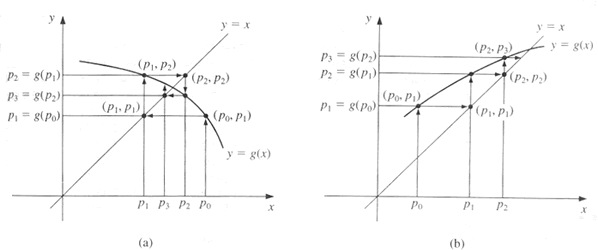

**Introducción:**

Para el siguiente laboratorio se trabajará como temática principal el método del punto fijo, donde por medio de diferentes ejercicios se busca entender el funcionamiento de dicha temática, buscando la gráfica del punto fijo en la función trabajada respecto a los intervalos dados, además de programar las diferentes formas de calcular el punto fijo, y como trabaja este respecto a la cantidad de iteraciones y punto inicial que se tome. Es necesario tener en cuenta que el método del punto fijo es un método iterativo que permite resolver distintos tipos de sistemas de ecuaciones no necesariamente lineales, muy utilizado para determinar las raíces de la función siempre y cuando se cumplan las reglas de convergencia. Las reglas del punto fijo funcionan de la siguiente manera: el punto fijo que viene de una función g, se le conoce como un numero p de tal manera que se tenga que g(p)=p. El propósito de esto es solucionar la ecuación cuando f(x)=0 y posterior a esto poder determinar los puntos fijos que tienen la función h(x). 

**1) Practice**

**Answer with your own words the following questions:**

-  **(0.2 points) What is a fixed point?**

El punto fijo es aquella función 𝑔 de la cual se tiene que al iterarla en repetidas veces, su resultado tendrá que converger en un punto especifico.

Para determinar que es el punto fijo, primero debemos tener en cuenta su funcionamiento, y es que teniendo una función 𝑔(𝑥)  la cual es evaluada en 𝑝𝑛 su resultado va a tender a un punto 𝑝, de tal manera que la función sea sobreescrita de la siguiente forma:  𝑔(𝑝)=𝑝. Es decir que el punto fijo es la función 𝑔 de la cual se tiene que al iterarla varias veces, su solución convergera en un punto especifico.

se evalua en  𝑔(𝑥) evaluada en 𝑝𝑛 su resultado tendera a un punto 𝑝, tal que 𝑔(𝑝)=𝑝.

- **(0.2 points) How to calculate a fixed point?**

1) Lo primero que se debe realizar los respectivos calculos para la función, es tener definida la función del punto fijo la cual es descrita como 𝑔(𝑥)

2) Se itera la función una y ptra vez, hasta que se pueda encontrar el valor más proximo al punto 𝑝.

3) Hay que tener en cuenta que tales iteraciones son progresivas debido a que a mayores veces que se haga la iteración será mas especifico o cercano el valor a 𝑝.

4) Al iterar la función  𝑔(𝑥), tenemos en cuenta que su valor inicial es $x_0 \;$por ende 𝑔′(𝑥0) <1, donde tenemos que y ∈(𝑎,𝑏) ∇ 𝑥 ∈ (𝑎,𝑏). De lo anterior se tiene que $x_n =g\left(x_n -1\right)$ cuando ya se encuentra despejada la función, y donde x se acerca a $p\ldotp$

- ** (0.2 points) What applications does the fixed point method have? **

Sabemos que el metodo del punto fijo es utilizado para resolver ecuaciones de la forma $x=g\left(x\right),$donde si la ecuación es del tipo $f\left(x\right)=0$entonces hacemos el despeje de x o en otros casos sumar x a ambos lados de la ecuación para organizarla y posteriora esto trabajar con ella, de tal manera que se encuentren las raíces de la función de las cuales se hablaba anteriormente. Dicho esto debemos definir un intervalo, y posterior a esto calcular el valor aproximado a la raíz que se busca determinar.

Al tener un valor cercano a la raíz, solo hace falta encontrar la función  𝑔 de tal manera que $x_{i+1} =g\left(x_i \right)\;$y donde g′($x_a$) <1.

- **(0.2 points) What condition must be satisfied to guarantee that a function has a fixed point?**

Existe una condición especifica para que se satisfaga la función del punto fijo. Digamos que existe un punto "$c$" el cual es fijo para la función $\mathrm{f}$ si se cumple el caso de $f\left(c\right)=c$, de tal manera que la imagen de c coincida con c. A partir de este planteamiento tenemos que al asumir que  𝑔 ∈ 𝐶[𝑎,𝑏], si tenemos un rango establecido para la busqueda de 𝑦=𝑔(𝑥) que cumpla el caso de 𝑦 ∈ (𝑎,𝑏) para todo 𝑥 ∈ (𝑎,𝑏), se tendrá que g tiene un punto fijo en el intervalo [𝑎,𝑏] y que por ende cumple la función..

- **(0.2 points) What condition must be satisfied to guarantee that the fixed point is unique?** 

En el caso de que se quiera encontrar una condición para que el punto fijo sea unico pues tenemos que 𝑔 ∈ 𝐶[𝑎,𝑏] donde si la función 𝑔′(𝑥) se define sobre (𝑎,𝑏) y a partir de esto se genera una constante positiva 𝐾<1 con |𝑔′(𝑥)|≤𝐾<1 que se cumple para todo 𝑥 ∈ (𝑎,𝑏), entonces tenemos a g como un punto fijo unico, lo cual satisace el planteamiento inicial.

**3.2 Applying**

**Use the fixed point iteration to find a fixed point for **$g\left(x\right)=1-\frac{x^2 }{4}$ on [0; 1]. Do five the iterations by hand. Choose the initial point.

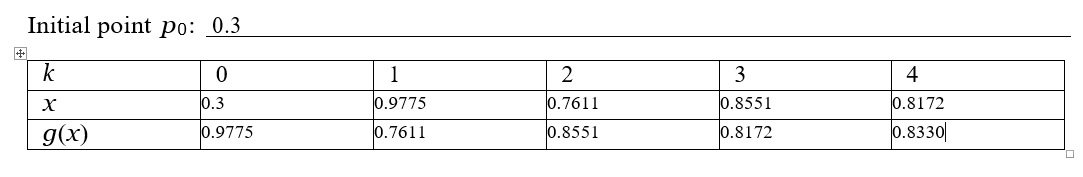

**3.3 Implementing**

- (0.5 points) Create a Matlab function called my_fixed_point to find a fixed point of a function over a given range. The arguments of the function must be: the function to be evaluated g(x) (as an inline function), the initial point of the range a, the final point of the range b, the initial iteration point p0, and the desired number of iterations. For instance, the sentences to find the fixed point of the exercise in 3.1 should look like:

**3.3.1**

fun = @(x) 1 - ${x\ldotp }^2$=4;

a=0;

b=1;

p0=0:5;

Iter=5;

P=my_fixed_point(fun,a,b,$p_0$,Iter);

fun = @(x) 1-(x.^2)/4;
p0=0.5;
Iter=5;
P=my_fixed_point(fun,p0,Iter)

P = 0.8203

Análisis: Para este primer punto se nos pide crear una función en matlab que sea capaz de calcular el puto fijo de la función que se nos da en el enunciado, que en este caso es 1-(x.^2)/4. A demás de esto el taller nos da el punto inicial o p0, y las iteraciones que debera hacer la función para cumplir el objetivo. Lo primero es definir las variables que vamos a utilizar. Posterior a esto en la parte de abajo del anexo vamos a crear el código que permita el claculo del punto fijo, lo primero será llamar la función que en este caso es P=my_fixed_point(fun,p0,Iter), luego definiremos nuestro p0, y crearemos un for el cual es utilizado par definir las iteraciones que llevará a cabo el código de acuerdo a la formula que calcula el punto fijo la cual está dada por P(k)=feval(fun,P(k-1)). Finalmente apreciamos que la función P que tenemos coincide con su imagen o en este caso el calculo.

**3.3.2**

- (0.5 points) Create a Matlab function called visual verification to visually show if the function has a fixed point over a range, and if that fixed point is unique. The arguments of the function must be: the function to be evaluated g(x) (as an inline function), the initial point of the range a, and the final point of the range b. For instance, the sentences to visually verify if the function of the exercise in 3.1 has an unique fixed point should look like:

fun = @(x) 1 - ${x\ldotp }^2$/4;

a=0;

b=1;

P=visual_verification(fun,a,b);

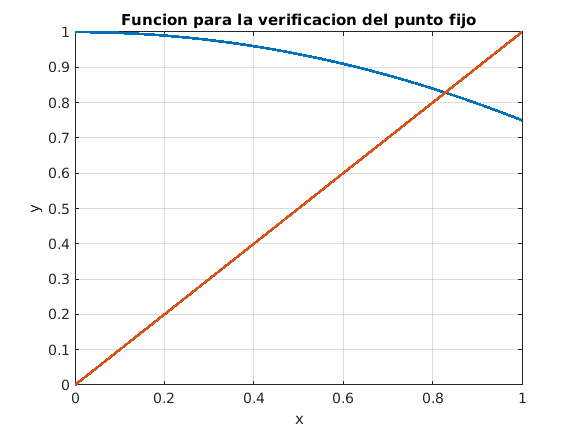

fun = @(x) 1-(x.^2)/4;
a=0;
b=1;
P=visual_verification(fun,a,b);

Análisis: Este segundo punto es bastante parecido al anterior, el enunciado nos da la misma función a evaluar, la diferencia es que en esta ocasión solo nos dan el intervalo a,b. Además quiere que programemos un código que pueda hacer ver en pantalla la gráfica del punto fijo de la anterior que nos dieron. Igual al ejercicio anterior definimos variables de la misma manera, pero a la hora de crear el código veremos diferentes similitudes, cabe resaltar que este estará en la parte de los anexos. Lo primero es llamar la función que en este caso será  P=visual_verification(fun,a,b), posterior a esto tendremos en cuenta que la recta será trasada en x, y definimos valores que va a calcular la función dentro del intervalo [a,b]. Posterior a este ya solo queda definir el titulo de la gráfica y definir el plano tanto x como y. 

**3.3.3**

- (0.5 points) Use the created function visual_verification to visually verify if $g\left(x\right)=1+\frac{2}{x}$ over [1; 5] has an unique fixed point, and use the created function *my_fixed_point* to find the fixed point of g(x) with $p_0$ = 4 and 100 iterations.

fun = @(x) 1+(2)./x;
a=1;
b=5;
p0=4;
max1=100;
P=my_fixed_point(fun,p0,Iter)

P = 3.4572

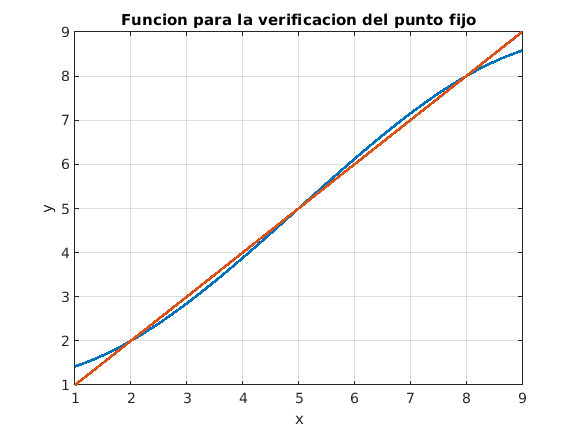

G=visual_verification(fun,a,b);

Análisis: Para este ejercicio nos dan una función diferente, en este caso sería $g\left(x\right)=1+\frac{2}{x}$, el objetivo es crear una función visual_verification con la cual uno pueda apreciar la gráfica de $g\left(x\right)=1+\frac{2}{x}$. De tal manera que se pueda ver su punto fijo unico, posterior a esto debemos usar la función my_fixed_point  con respecto al p0= y a las 100 iteraciones que nos dan. A la hora de programar la función, primero tenemos que definir las variables, lo primero será definir la nueva función que nos dan, y posterior a esto definir los intervalos a,b con los que se va a trabajar, además se define el punto inicial o p0, y las iteraciones que va a hacer la función, la cual en este caso serán 100. Finalmente usamos la verificación visual para poder apreciar la gráfica con respecto  a esas incognitas que nos piden definir.

**3.4 Implementing**

The network bandwidth allocation problem is one of the central issues in modern communication networks. When a data rate is allocated to a source participating in a network, it derives a utility, which is modeled as a value of a concave function. The well known utility function of each source s is given by the following function, which satisfies the strict concavity, for all x ∈R+,

#### 
$$u_s \left(x\right)=w_s \textrm{logx}$$


where ωs > 0 is the weighted parameter for the source s, and x is the allocated data rate to the network. The share allocated data rate to each source must be regulated with a control mechanism to prevent network congestion. A network congestion is generated when the utility of any source in the network is equal to the allocated data rate in the network.

- (1.0) Use the created functions to find the allocated data rate x which could generate a network congestion due to a source with ωs = 4.8, where x ∈ [5,15]. Choose the initial point p0.

ws=4.8;
fun=@(x) ws.*log10(x);
a=5;
b=15;
p0=10;
Iter=15;
P=my_fixed_point(fun,p0,Iter)

P = 1.2190 + 0.6876i

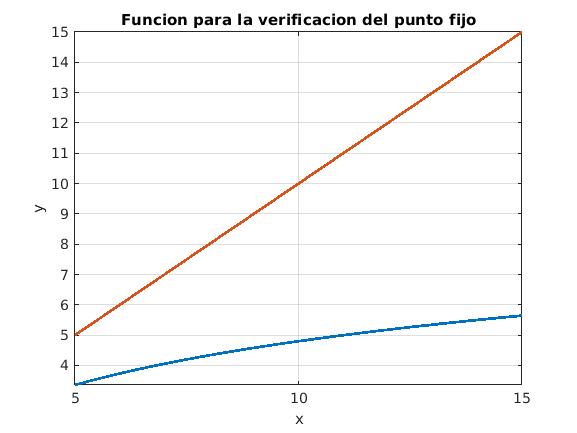

G=visual_verification(fun,a,b);

Análisis: en este ejercicio vamos a tratar una aplicación como se ve en el problema del ancho de banda, en el cual se nos da una función especifica para trabajar $u_s \left(x\right)=w_s \textrm{logx}$. Y además de esto se nos dan algunas otras variables, cabe resaltar que somos nosotros quienes definimos el p0 y las respectivas iteraciones.Lo primero entonces es de igual manera definir las variables, definir la función con la que se va a trabajar, en este caso a=5 yel p0 inicla que yo elegí fue p0=10, y las iteraciones fueron iter =15, finalmente calculamos el punto fijo nombrando las variables a evaluar, y gráficamos la función respecto a sus variables  b=15.

**3.5 Proposing**

• Propose an applicated problem in which the fixed point iteration can be used.

• Solve the proposed problem using the created functions.

fun = @(x) 1/2.*(x+(3/x));
a= -3;
b= 2;
p0=2;
Iter=20;
P=my_fixed_point(fun,p0,Iter)

P = 1.7321

Parte de verificación visual:

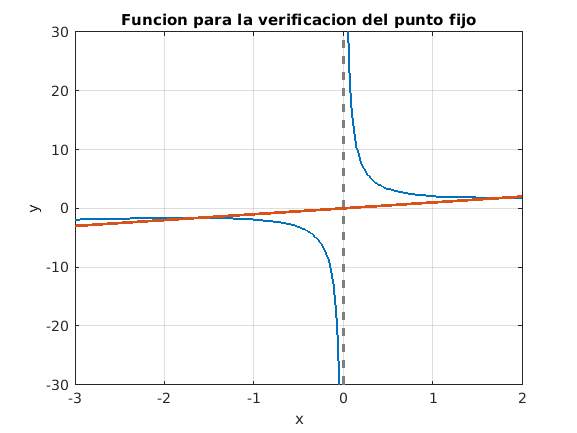

G=visual_verification(fun,a,b);

Análisis: Para el ultimo ejercicio se nos pide usas todo el conocimiento aprendido y de igual manera las funciones programada de tal manera que uno como estudiante pueda plantear una función propia donde se pueda calcular el punto fijo y además de esto se pueda definir la gráfica donde se pueda ver la función en los intervalos de tiempo definidos. En cuanto al código de la función pues es casi lo mismo que los anteriores ejercicios, ya que se define las variables, solo que está vez se debe tener en cuenta que para programar dicha función ya se debe haber tenido en cuenta que dicha función si es funcional dentro de este procedimiento respecto al punto inicial que se le da, y los intervalos que se definen de la función. Se puede decir que el ejercicio cumple con los criterios de evaluación si se logra encontrar que dicha función tenga un punto fijo, y que de la misma manera la gráfica esté adecuada a la función descrita.

**Anexos**

**3.3.1**

**Función para la iteración **

function P=my_fixed_point(fun,p0,Iter)
P(1)=p0;
for k=2:Iter
    P(k)=feval(fun,P(k-1));
end
P=P(end);
end

**3.3.2**

**Función de verificación**

function P=visual_verification(fun,a,b)
recta = @(x)x;
fplot(fun,[a,b],'Linewidth',2);
hold on
P=fplot(recta,[a,b],'LineWidth',2);
hold off
grid on
title ('Funcion para la verificacion del punto fijo')
xlabel('x');
ylabel('y');
end